# 電**力**データのダウンロード

このスクリプトでは、ニューヨークISOから**電力負荷**データをダウンロードし、前処理を行います。[http://mis.nyiso.com/public/](http://mis.nyiso.com/public/)

firstmonth = '2015-01-01'; % year-month-date
lastmonth = '2020-12-31'; % year-month-date
replaceFlag =  false; 


MATLABコードを見せる・隠すを切り替えたい場合、「ビュー」タブの右側にあるコードを非表示(Hide code)ボタンを切り替えてください。

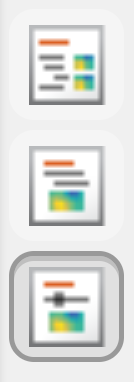

clf;
% dates = (datetime(firstmonth,"Format","yyyyMMdd"):calmonths(1):datetime(lastmonth))';
dates = (datetime(firstmonth,"Format","yyyyMMdd","Locale","en_US"):calmonths(1):datetime(lastmonth,"Locale","en_US"))';

% Create directory for zip files if it does not exist
ziploc = uigetdir(pwd(),"Select a folder to download data");
addpath(ziploc);

% Search zip directory for existing zip files
d = dir(fullfile(ziploc,'*.zip'));

if ~replaceFlag % if we don't want to replace zips...
    % get the months for existing zips
    zipnames = string({d.name});
    existzips = datetime(extractBetween(zipnames,"HistLoad",".zip"),"InputFormat","yyyyMMdd");
    
    % find which zips exist in the list to download that do not exist in
    % zip directory
    [~,idx] = setdiff(dates,existzips);
    
    % filter out dates that have already been downloaded
    dates = dates(idx);
end

% Download files and save to the chosen location
numdates = length(dates);
for ii = 1:numdates
    %name of zip file
    filename = string(dates(ii)) + "pal_csv.zip";
   
    %location of zip file
    url = "http://mis.nyiso.com/public/csv/pal/" + filename;
    
    %destination on local computer
    filedestination = fullfile(ziploc,"HistLoad" + string(dates(ii))+ ".zip");
    disp("Downloading " + ii + " of " + numdates + " -> " + filename)
    try
        %save from web to local directory
        websave(filedestination,url);
        disp('Download complete.');
    catch ME
        disp("Failure: " + ME.message);
    end    
end

fileloc = fullfile(ziploc, "HistLoad");
for ii = 1:numdates
    unzip(fullfile(ziploc, "HistLoad" + string(dates(ii)) + ".zip"), fileloc)
end

if exist(fullfile(ziploc,"nyiso_original.mat"),"file") && ~replaceFlag    
    disp("MAT files exist in " + ziploc)
else
    % Aggregate all data files to a table
    disp("Aggregating data from all files")
    paldatafiles = fullfile(ziploc,"HistLoad/*pal.csv");
    ds = datastore(paldatafiles,'TextscanFormats',{'%{MM/dd/yyyy HH:mm:ss}D','%s','%C','%f','%f'}, 'SelectedVariableNames', {'TimeStamp', 'Name', 'Load'}, 'ReadSize', 1e6);
    
    N = 4;
    nyisoRaw = cell(N,1);
    for ii = 1:N
        % For each worker, grab its partition of the datastore
        subds = partition(ds,N,ii);
        nyisoRaw{ii} = readall(subds);
    end
    
    nyisoRaw = vertcat(nyisoRaw{:});
    nyisoRaw.Properties.VariableNames{1} = 'Date';
    
    nyisoUnstack = unstack(nyisoRaw,'Load','Name','VariableNamingRule',"modify");
    nyisoUnstack = sortrows(nyisoUnstack,'Date');
    save(fullfile(ziploc,"nyiso_original.mat"),"nyisoUnstack")
    
    % Preprocess data.
    disp("Preprocessing and cleaning data")
    nyisoRetimed = table2timetable(nyisoUnstack);
    nyisoRetimed = retime(nyisoRetimed,nyisoRetimed.Date(1):minutes(5):nyisoRetimed.Date(end), 'linear');
    
    nyisoRemove = energyCleanup(nyisoRetimed);
    nyisoFilled = fillmissing(nyisoRemove,'spline','EndValues','none');
    
    % create trailing moving average with a 1 hour window
    nyisoSmooth = nyisoFilled;
    nyisoSmooth{:,1:end} = movmean(nyisoFilled{:,1:end},[11,0]);
    
    nyiso = nyisoSmooth;
    save(fullfile(ziploc,"nyiso_cleaned.mat"),"nyiso")
    
    disp("MAT files saved in " + ziploc);

end

MAT files exist in C:\Users\megumif\OneDrive - MathWorks\Documents\MATLAB\CSEActivity\courseware\regression-basics


function idx = findSpikes(y,np,sd,lt,ut)
% idx = findSpikes(y,np,sd,lt,ut)
%
% findSpikes uses slope outliers to detect spikes in a signal. The slopes
% between consecutive points are flagged as outliers if they are +/- 'sd'
% standard deviations from the mean slope. If an outlier slope in one
% direction is followed within 'np' points of an outlier slope in the
% opposite direction, all points between those two slopes are flagged.
%
% Inputs:
%   y       input signal containing spikes to be identified
%   np      maximum number of points in spike (default: 1)
%   sd      number of standard deviations from mean slope to use as
%           threshold for slope outlier (default: 2.5)
%   lt      lower threshold, all points below this will be flagged (default: -inf)
%   ut      upper threshold, all points above this will be flagged (default: inf)
%
% Outputs:
%   idx     logical index of points that were flagged as spikes

% default value for np is 1
if nargin < 2 || isempty(np)
    np = 1;
end
% default value for sd is 2.5
if nargin < 3 || isempty(sd)
    sd = 2.5;
end
% default value for lt is -inf
if nargin < 4 || isempty(lt)
    lt = -inf;
end
% default value for ut is inf
if nargin < 5 || isempty(ut)
    ut = inf;
end

% flag anomalies below lower threshold or above upper threshold
idxout = y < lt | y > ut;

% calculate the slope
dy = diff(y);

% create the threshold
st = nanstd(dy); % standard deviation of the slope
mn = nanmean(dy); % mean of the slope

% where do large changes happen
idxup = dy > mn+sd*st; % large positive change
idxdown = dy < mn-sd*st;  % large negative change
idxuploc = find(idxup); % locations where large positive change occurred
idxdownloc = find(idxdown); % locations where large negative change occurred
idxup_anom = false(length(idxup),1); % preallocate array for storing location of positive anomalies
idxdown_anom = false(length(idxdown),1); % preallocate array for storing location of negative anomalies

% identify anomalies in the positive direction, e.g. large positive
% slope followed by large negative slope within a certain number of
% measurements
for ii = 1:length(idxuploc) % for each location where large positive slope exists...
    % find places where the location of large negative slope comes after a
    % positive anomaly within a certain threshold of points
    idxmatch = idxdownloc-idxuploc(ii) <= np & idxdownloc-idxuploc(ii) > 0;
    % if there's any large negative slopes that match the criteria
    if any(idxmatch)
        % find where they occur, and from the location where the positive
        % slope is recorded to the location before the negative slope is
        % recorded set the value to true, signaling an anomaly
        m = find(idxmatch);
        % if there are multiple large down slopes in range, pick the last
        % one to capture the full anomaly
        idxup_anom(idxuploc(ii):idxdownloc(m(end))-1)=true;
    end
end
% identify anomalies in the negative direction
for jj = 1:length(idxdownloc)
    idxmatch = idxuploc-idxdownloc(jj) <= np & idxuploc-idxdownloc(jj) > 0;
    if any(idxmatch)
        m = find(idxmatch);
        idxdown_anom(idxdownloc(jj):idxuploc(m(end))-1)=true;
    end
end
% combine the different anomalies
idx = idxup_anom | idxdown_anom;
% pad idx because we lost a point when subtracting for the slope
idx = [false;idx] | idxout;
end

function tbl = energyCleanup(tbl)

% loop through each column of the table
for ii = 1:width(tbl)
    ul = [];
    % specifying the upper limit isn't necessary for most regions
    % however it can help with the NORTH region as some large spikes
    % can be difficult to identify without it
    if strcmp(tbl.Properties.VariableNames{ii},'NORTH')
        ul = 1000;
    end
    % find the spikes to remove
    idxRemove = findSpikes(tbl.(ii),14,5,5,ul);
    % remove them
    tbl.(ii)(idxRemove) = NaN;
end

% add the time zone
tbl.Date.TimeZone = 'America/New_York';

% make sure it is still on the five minute interval
tbl = retime(tbl,tbl.Date(1):minutes(5):tbl.Date(end));
end